# Are We Making Pizzas With Too Much Cheese?

## Introduction

Our pizza shop allows customers to order pizzas with light, regular, or heavy cheese. The table below lists the expected amount of cheese used for each level. 

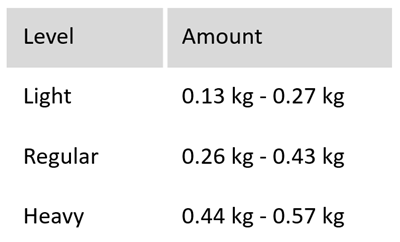

However, these ranges are only approximate, so some pizzas may have heavy cheese even though they weren't ordered with it. How can you see if this occurs? In this problem, you'll use relational and logical operators to answer whether some pizzas are made with too much cheese.

In the pizza dataset, pizzas ordered with heavy cheese have the phrase "heavy cheese" in the `Description` variable. Here's an example:

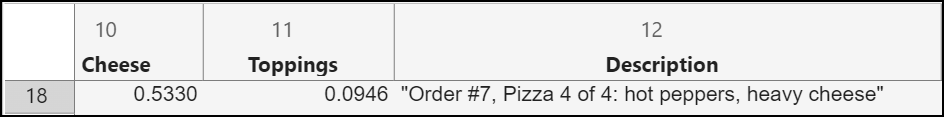

## Task

To start, use the `importOrders.mlx` script you created previously to import the `pizzaOrderHistory.csv` dataset to a table named `orders`. If you don't have that file, follow along with the [Importing and Working with Tabular Data](https://courses.edx.org/courses/course-v1:MathWorks+intro_matlab+2T2021/jump_to_id/9d668aced7c3441490651fcdc860e328) video to create it.

Your task is to identify pizzas with a heavy amount of cheese but *don't* contain "heavy cheese" in the description. There are four sub-tasks:

- Identify pizzas that use more than 0.43 kg of cheese. Use a relational operator and the variable `orders.Cheese` to create a logical variable that identifies these pizzas. Store the result in a variable named `heavyAmount`. See the documentation pages of [relational](https://www.mathworks.com/help/matlab/relational-operators.html) and [logical](https://www.mathworks.com/help/matlab/logical-operations.html) operators for reference. 

- Identify pizzas **without** the "heavy cheese" label. Use the function [`contains`](https://www.mathworks.com/help/matlab/ref/contains.html) and a logical operator to identify these pizzas. Store the result in a logical variable named `noHeavyLabel`. Note that the function `contains` returns a value of 1 when a pattern is found within a string. For example, `contains(orders.Description,"pineapple")` would identify pizzas with `"pineapple"` in the description.

- Identify pizzas with the heavy cheese amount and no heavy cheese label. Store the result in a logical variable named `extraCheese`. 

- Calculate the percentage of pizzas in the dataset that have extra cheese using the logical variable you just created. Store the percentage value in a variable named `percentExtraCheese`.

### Code

## Check your work

Is your code producing the expected results?

Hints for common issues are provided below. If you still have questions, consider asking them in the course discussion forum.

**Task 1**

The variable `heavyAmount` should be a logical variable with a value of 1 for any pizzas that contain more than 0.43 kg of cheese.

Hints:

- Use the cheese amounts recorded in the variable `orders.Cheese` for this task. 

- Use the relational operator ">" to assess whether the values are greater than the expected amount.

**Task 2**

The variable noH`eavyLabel` should be a logical variable with a value of 1 for any pizza whose description doesn't contain the phrase "heavy cheese". 

Hints:

- The function `contains` requires two arguments: the string variable to search, and the pattern to look for within the string variable. In this case, the two arguments should be the string variable `orders.Description` and the phrase `"heavy cheese"`.

- Use the operator `"~"` for a logical NOT operation that turns values of 1's into 0's and 0's into 1's. For example, with a variable named x, the statement `~x` will return a new logical variable with flipped 1's and 0's.

**Task 3**

The variable `extraCheese` should be a logical variable with a value of 1 for pizzas with cheese usage above 0.43 kg but don't contain the phrase "heavy cheese" in the variable `Description`. 

Hints:

- Use the operator "&" for a logical "AND" operation, since you want the values that have the heavy amount AND don't have the heavy label.

**Task 4**

The variable `percentExtraCheese` should be the percentage of pizzas with too much cheese, meaning the percentage of values in `extraCheese` that are equal to 1. 

**Hints:**

- Use the function `nnz` to count the number of non-zero values in the logical variable `extraCheese`.

- Use the function `length` with `extraCheese` to get the total number of pizzas.

- Make sure to multiply by 100 to convert the fraction into a percentage value.

## Conclusion

Once you are satisfied with your results, return to the quiz and enter the value for `percentExtraCheese` as the answer for Question 5. 

Was your value correct? If not, don't worry. Iterating on your code is a common part of the programming process! Review the hints provided above for each task to improve your solution. 

*Copyright 2025 The MathWorks, Inc.*